**谷底宽高比（VF）**

VF 值可以反映抬升速率和构造活动性之间的关系，由谷底宽度比谷底高程得到。该参数的测定位置均距支流出水口约1.5 ~2.0 km处，其计算公式为：


$$\textrm{VF}=\frac{2V_{\textrm{fw}} }{\left(E_{\textrm{ld}} -E_{\textrm{sc}} \right)+\left(E_{\textrm{rd}} -E_{\textrm{sc}} \right)}$$


式中，$V_{\textrm{fw}}$ 代表河谷底部宽度，$E_{\textrm{ld}}$ 代表河谷左侧分水岭高程值，$E_{\textrm{rd}}$ 代表河谷右侧分水岭高程值，$E_{\textrm{sc}}$ 代表河谷底部平均高程值。VF 值与构造隆升速率呈负相关性，较低的 VF 值表示较高的隆升速率，深切河谷发育，地貌显现“V”字形，表示构造活动较为活跃；较高的 VF 值表示较低的隆升速率，宽缓河谷地貌发育，反映构造活动性弱，VF值可以分为3个等级评价断裂活动程度。对至少三个横截面剖面取平均值，以获得盆地的平均VF值。VF值可分为VF ≤ 0.5、0.5 ≤ VF < 1.0和VF ≥ 1三类，分别为高、中、低构造活动性。

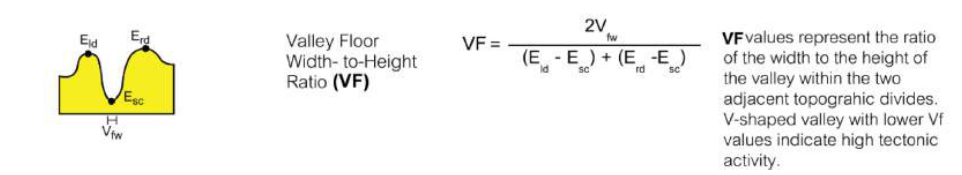

function VF_index = ttb_calculate_vf_index(dem, main_stream, V_fw_min, V_fw_max, interval_num, show)
    if V_fw_min > V_fw_max || interval_num < 0
        error("参数错误");
    end

    [main_stream_x, main_stream_y] = STREAMobj2XY(main_stream);
    stream_segment_num = length(main_stream_x) - 2; % 最后一个坐标为 NaN 不计入
    [~, basin_x, basin_y] = GRIDobj2polygon(drainagebasins(FLOWobj(dem)));

    if show
        figure;
        imageschs(dem);
        hold on;
        plot(main_stream_x, main_stream_y, 'Color', 'r', 'LineWidth', 2);
        plot(basin_x, basin_y, 'Color', 'k', 'LineWidth', 5);
    end

    % 计算总距离
    total_distance = 0;
    for i = 1 : stream_segment_num
        total_distance = total_distance + Utils.get_distance( ...
            main_stream_x(i), main_stream_y(i), ...
            main_stream_x(i + 1), main_stream_y(i + 1)...
        );
    end

    % 加载v_fw
    V_fw = linspace(V_fw_min, V_fw_max, interval_num);

    % 按照总距离等间距分割，获取待计算点的索引
    distance = 0;
    % 哨兵元素，为了后续确定方向
    idx = [1];
    for i = 1 : stream_segment_num
        distance = distance + Utils.get_distance( ...
            main_stream_x(i), main_stream_y(i), ...
            main_stream_x(i + 1), main_stream_y(i + 1)...
        );
        if distance > total_distance / (interval_num+1)
            % 记录需要计算的点的索引
            idx = [idx, i];
            % 重置 distance
            distance = 0;
        end
    end
    % 哨兵元素，为了后续确定方向
    idx = [idx, length(main_stream_x)-1];
    
    % 计算 VF
    VF_index = 0;
    counter = 1;
    % 中间 interval_num 个待计算点
    for j = 2 : length(idx)-1
        i = idx(j);
       
        % 待计算点坐标
        mid_point = [(main_stream_x(i+1) + main_stream_x(i)) / 2, ...
                     (main_stream_y(i+1) + main_stream_y(i)) / 2];

        % 按照待计算点的前后两点确定方向
        dx = main_stream_x(idx(j+1)) - main_stream_x(idx(j-1));
        dy = main_stream_y(idx(j+1)) - main_stream_y(idx(j-1));

        % 计算垂直向量
        perpendicular_vector = [-dy, dx];

        % 归一化垂直向量
        perpendicular_vector = perpendicular_vector / norm(perpendicular_vector);

        % 垂直向量从线段中点往两边延申
        L = 1e10; % 延申倍数
        point1 = mid_point - perpendicular_vector * L;
        point2 = mid_point + perpendicular_vector * L;

        % 获取垂直向量与流域多边形的交点
        [intersect1_x, intersect1_y] = polyxpoly([mid_point(1), point1(1)], ...
                                              [mid_point(2), point1(2)], ...
                                              basin_x, basin_y);
        [intersect2_x, intersect2_y] = polyxpoly([mid_point(1), point2(1)], ...
                                              [mid_point(2), point2(2)], ...
                                              basin_x, basin_y);
        
        % 补丁：偏移一个单位，使得点不会超出范围
        intersect1_x = intersect1_x + perpendicular_vector(1);
        intersect1_y = intersect1_y + perpendicular_vector(2);
        intersect2_x = intersect2_x - perpendicular_vector(1);
        intersect2_y = intersect2_y - perpendicular_vector(2);

        % 交点可能有多个，取距离待计算点最近的一个
        if length(intersect1_x) > 1
            min_distance = 2e10;
            min_idx = 0;
            for k = 1 : length(intersect1_x)
                distance = sqrt((intersect1_x(k) - mid_point(1))^2 + (intersect1_y(k) - mid_point(2))^2);
                if distance < min_distance
                    min_distance = distance;
                    min_idx = k;
                end
            end
            intersect1_x = intersect1_x(min_idx);
            intersect1_y = intersect1_y(min_idx);
        end
        if length(intersect2_x) > 1
            min_distance = 2e10;
            min_idx = 0;
            for k = 1 : length(intersect2_x)
                distance = sqrt((intersect2_x(k) - mid_point(1))^2 + (intersect2_y(k) - mid_point(2))^2);
                if distance < min_distance
                    min_distance = distance;
                    min_idx = k;
                end
            end
            intersect2_x = intersect2_x(min_idx);
            intersect2_y = intersect2_y(min_idx);
        end

        if show
            scatter(intersect1_x, intersect1_y, 50, 'r', 'filled', 'MarkerEdgeColor', 'k');
            scatter(intersect2_x, intersect2_y, 50, 'b', 'filled', 'MarkerEdgeColor', 'k');
            scatter(mid_point(1), mid_point(2), 50, 'g', 'filled', 'MarkerEdgeColor', 'k');
            plot([intersect1_x, intersect2_x], [intersect1_y, intersect2_y], 'Color', 'k', 'LineWidth', 1)
        end

        % 按照交点坐标读取高程
        E_sc = Utils.get_elevation(dem, mid_point(1), mid_point(2));
        E_side1 = Utils.get_elevation(dem, intersect1_x, intersect1_y);
        E_side2 = Utils.get_elevation(dem, intersect2_x, intersect2_y);

        VF_index = VF_index + 2 * V_fw(counter) / (E_side1 + E_side2 - 2 * E_sc);

        counter = counter + 1;
    end

    VF_index = VF_index / interval_num;
end